# 07 HO: Reduced Integration

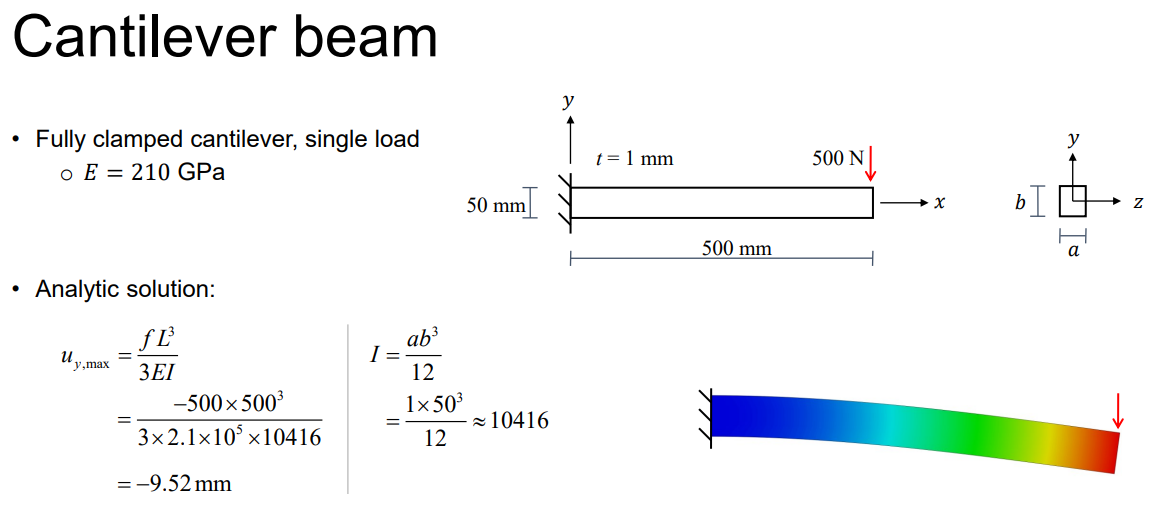

clear all; close all;

## Given parameters

E = 2.1e5;
nu = 0.3;

C = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0,  0, (1 - nu) / 2];

## Model definition

lx = 500;       % Length in x
ly = 50;        % Length in y
f0 = -500;      % Point load
t = 1;          % Thickness

% Analytic solution
I = (ly^3 * t) / 12;

uAnalytic = (f0 * lx^3) / (3 * E * I)

uAnalytic = -9.5238

#### Prepare geometry and mesh

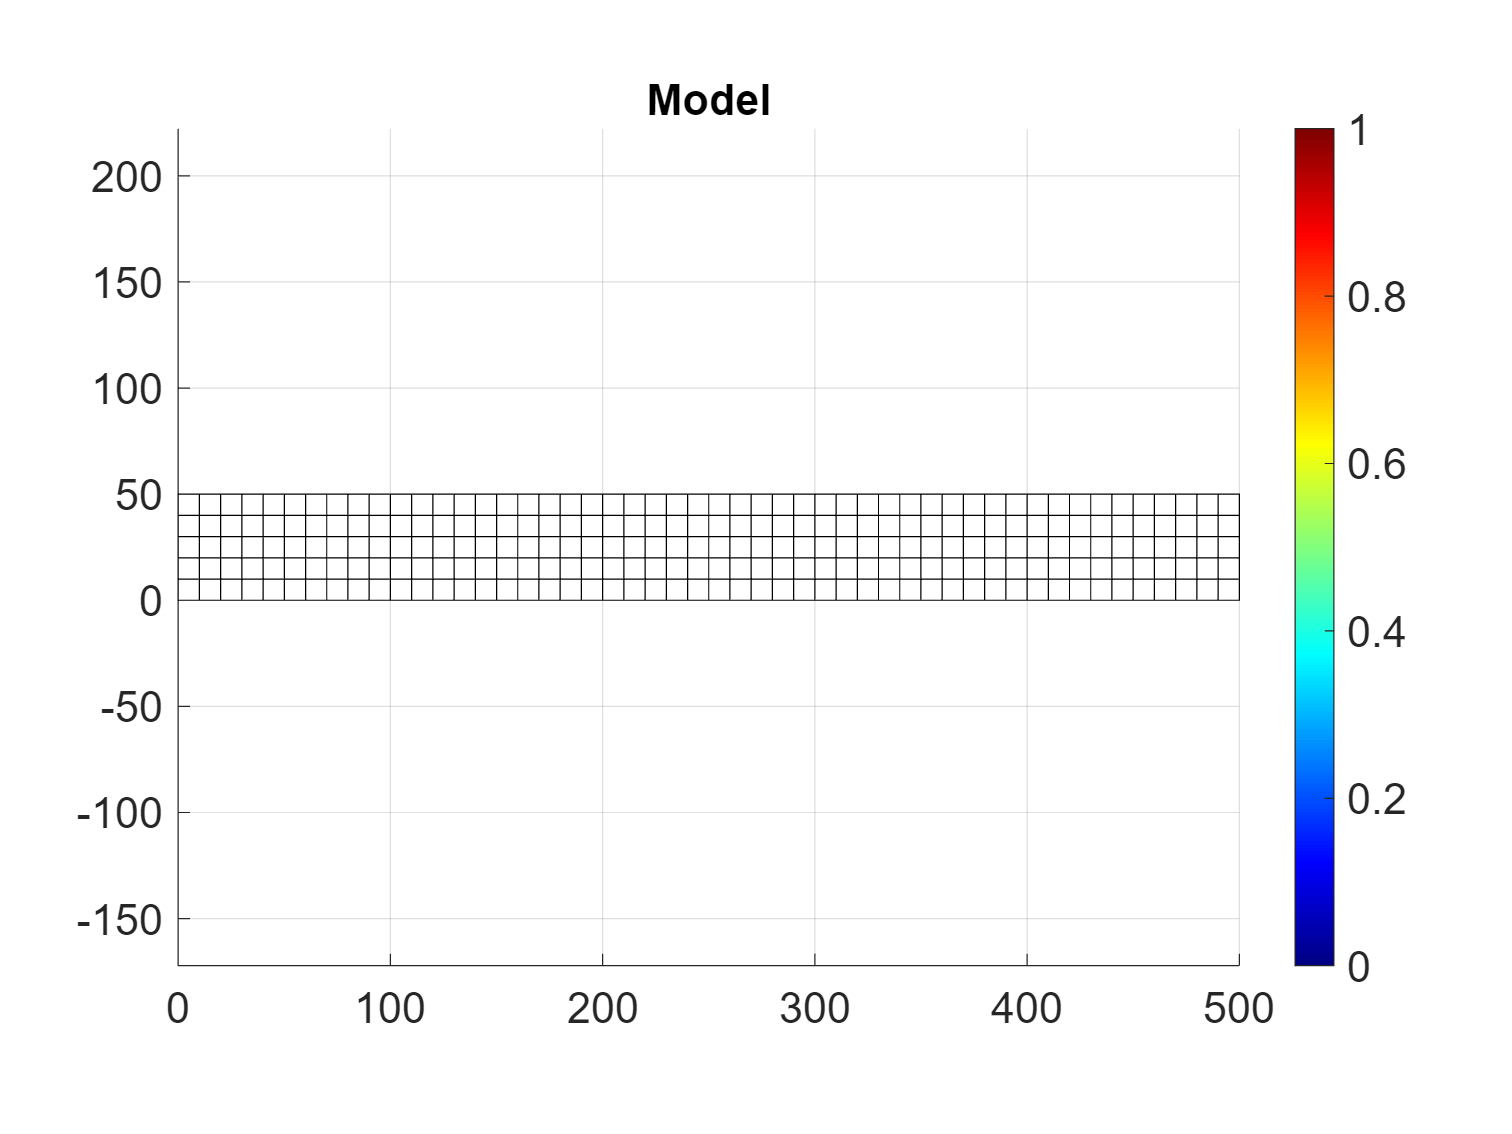

nelx = 50;      % Number of elements in x
nely = 5;       % Number of elements in y

elementType = 'quad';    % 'quad' or 'tri' for quadrilaterals or triangles, respectively
[nodes, elements] = rectangleMesh([lx, ly], [nelx, nely], elementType);

plotElements(nodes, elements, 'Model'); grid on;

nNodes = size(nodes, 1);
dofPerNode = 2;

nElements       = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement   = dofPerNode * nodesPerElement;
elementDOFs     = globalElementDOFs(elements, 2);

% Initialize system matrices
K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);

% Set up stiffness matrix by looping over elements
for e = 1 : nElements
    % Get element nodes
    elementNodes = nodes(elements(e, :), :);

    % Check elementType and compute element stiffness accordingly
    if strcmp(elementType, 'quad')
        KE = elementStiffnessLinearQuad(C, elementNodes);
    elseif strcmp(elementType, 'tri')
        KE = elementStiffnessLinearTri(C, elementNodes);
    else
        error('Stiffness matrix for %s not implemented', elementType);
    end
    
    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elementDOFs(e, :), elementDOFs(e, :)) = K(elementDOFs(e, :), elementDOFs(e, :)) + KE;
end

% Load
f([2 * (nelx + 1) * (nely + 1)]) = f0;

#### Boundary conditions

fixedNodes = find(nodes(:, 1) == 0);                % on the left edge, where x = 0 
fixeddofs = [2 * fixedNodes - 1; 2 * fixedNodes];

#### Solve system

freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);

#### Plot displacement as x0 + u

scale = 5;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
uMagnitude = vecnorm(uNodes, 2, 2);
plotElements(nodes + scale * uNodes, elements, '|u|', uMagnitude);

uTip = u(2 * (nelx + 1))

uTip = -9.3878

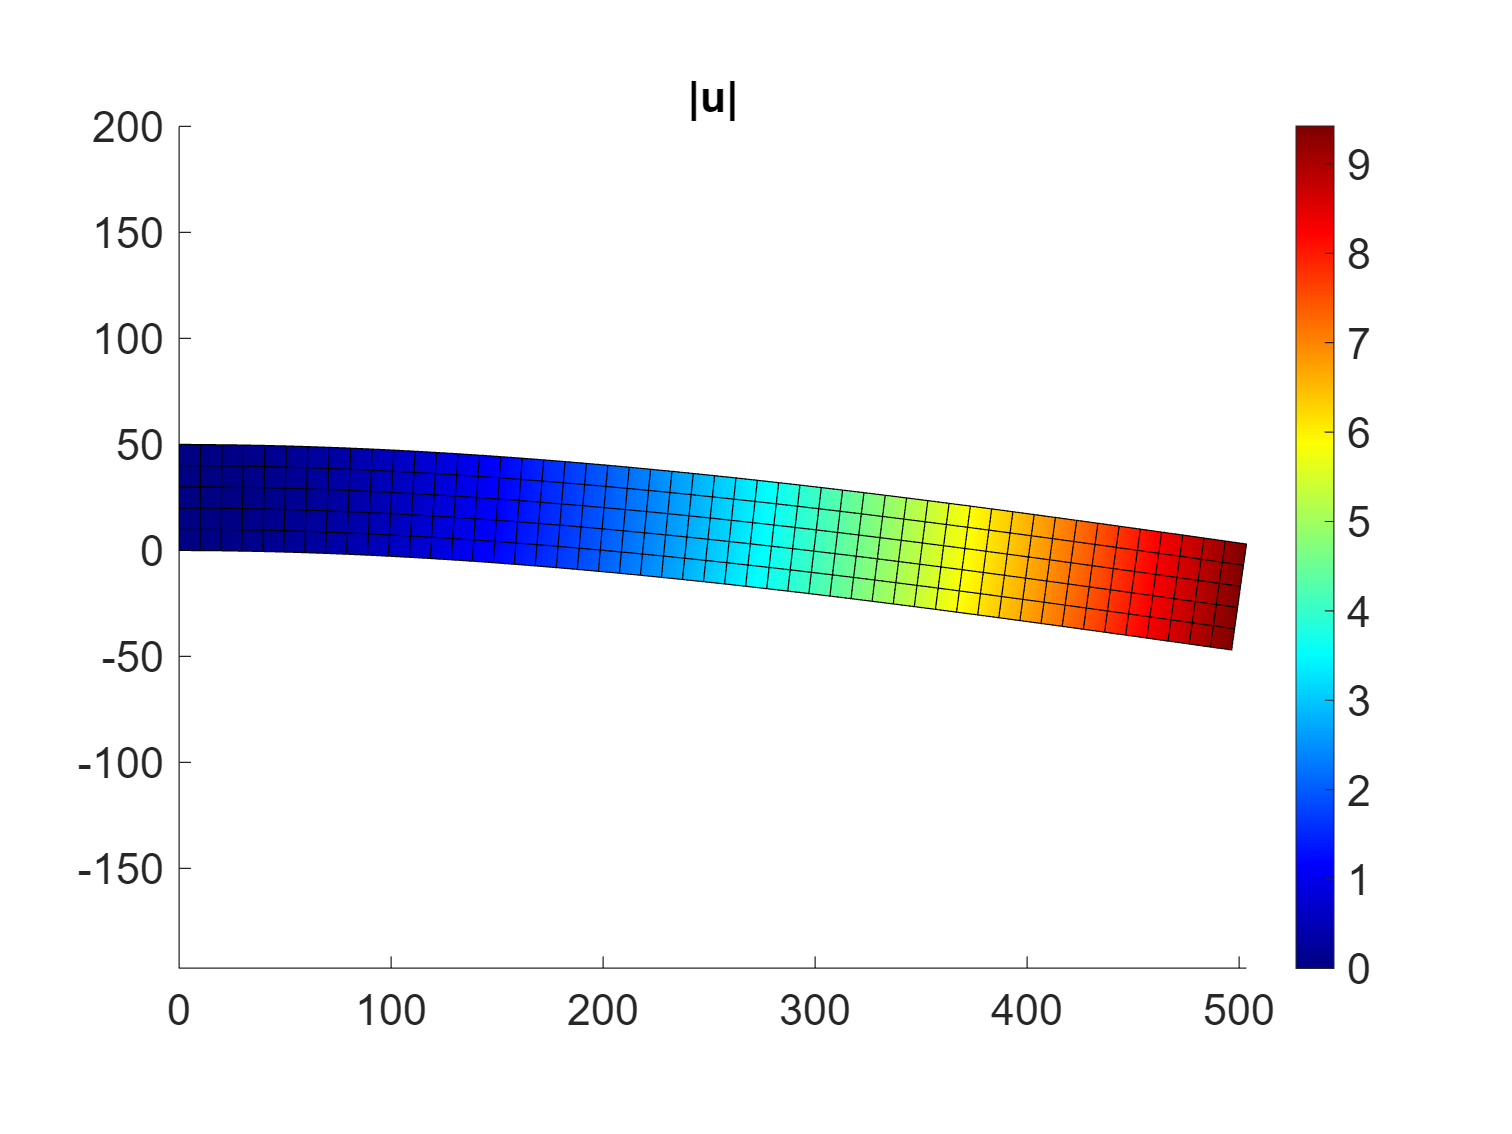

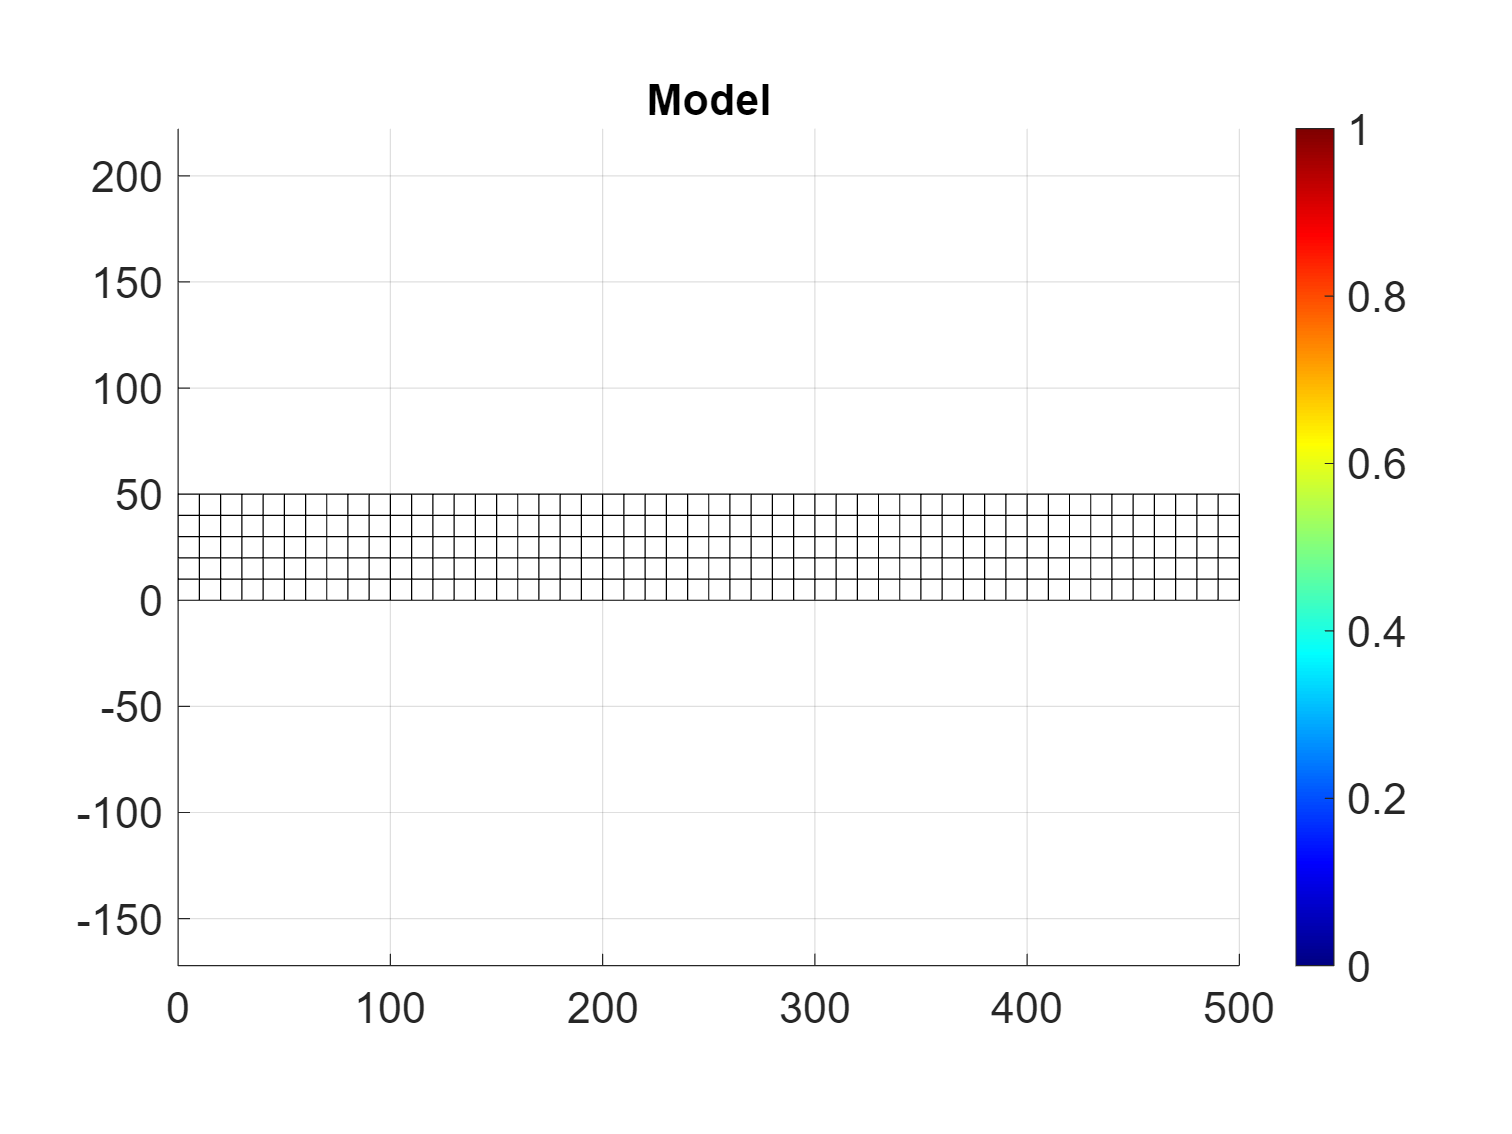

fh = findall(0,'Type','Figure');
set( findall(fh, '-property', 'fontsize'), 'fontsize', 18)

# HW 01: Triangular Elements

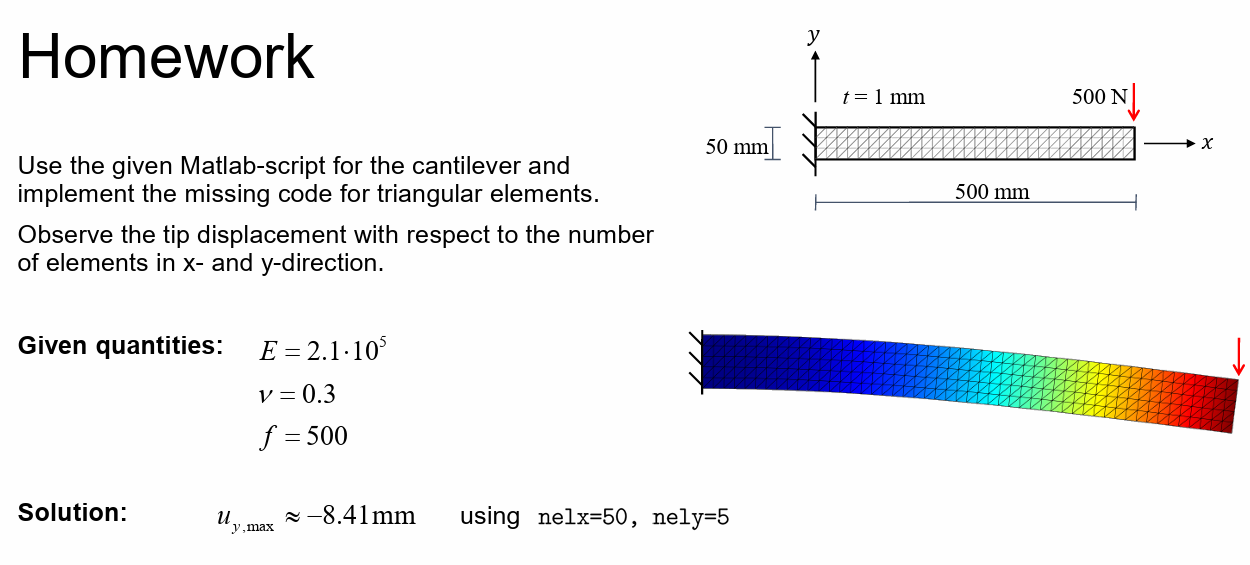

E = 2.1e5;
nu = 0.3;

C = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0,  0, (1 - nu) / 2];

lx = 500;       % Length in x
ly = 50;        % Length in y
f0 = -500;      % Point load
t = 1;          % Thickness

% Analytic solution
I = (ly^3 * t) / 12;

uAnalytic = (f0 * lx^3) / (3 * E * I)

uAnalytic = -9.5238

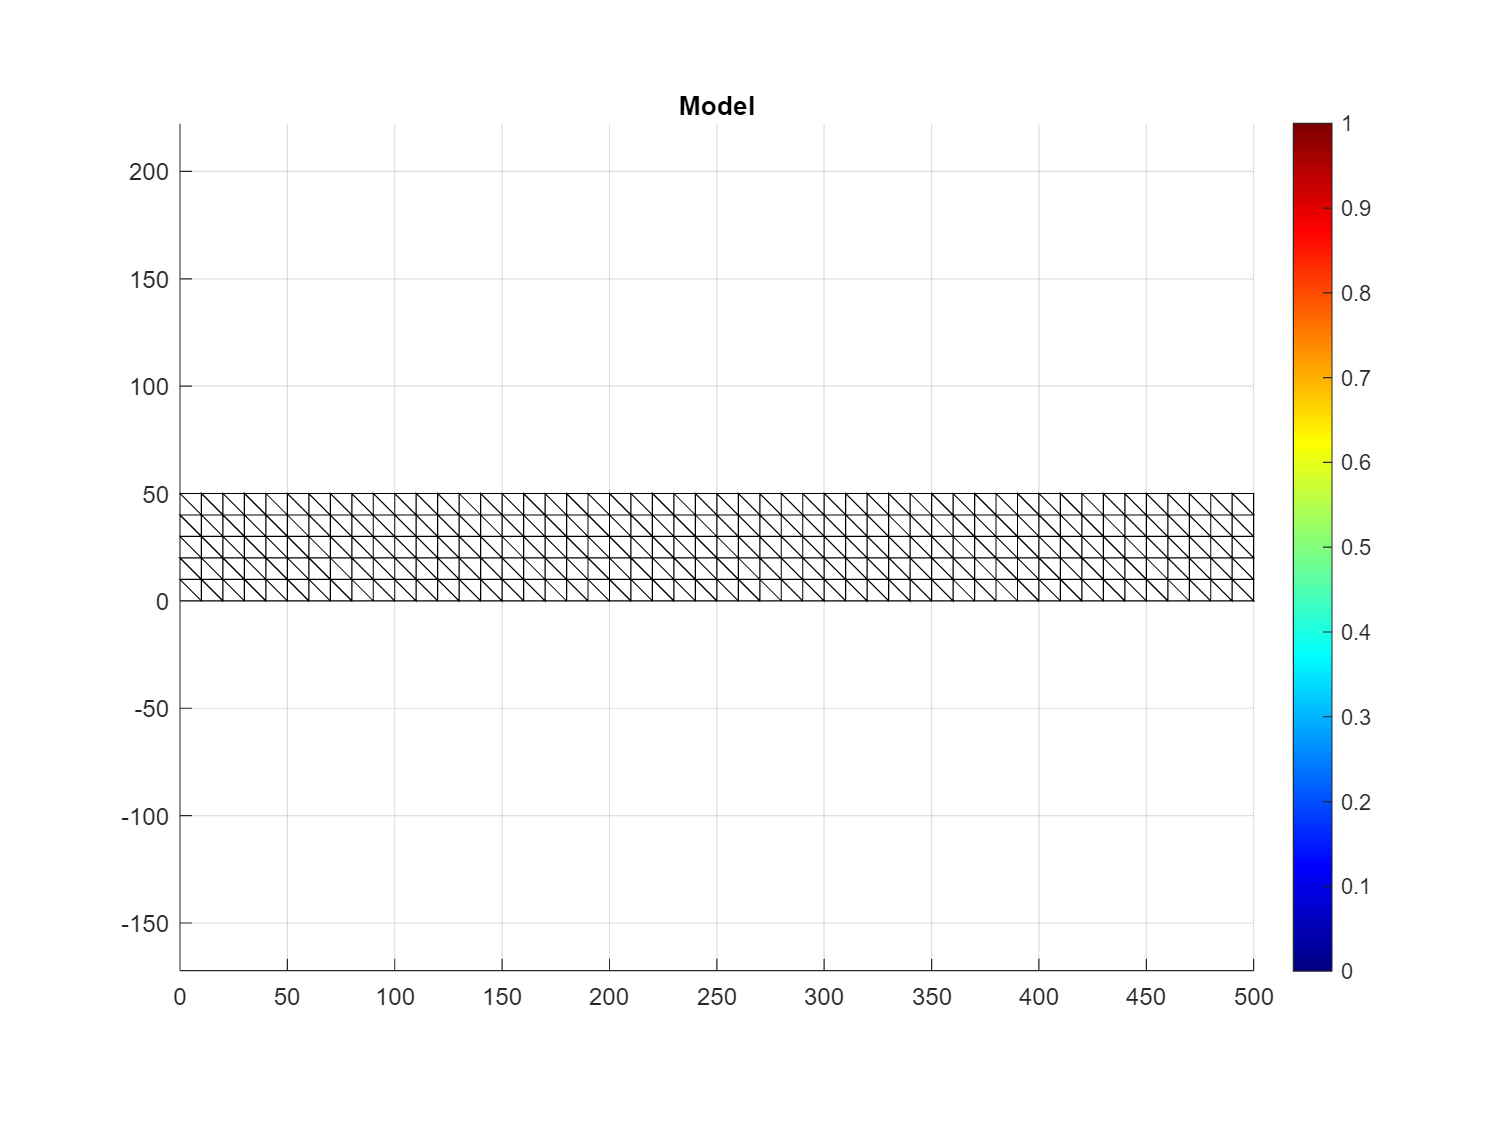

nelx = 50;      % Number of elements in x
nely = 5;       % Number of elements in y

elementType = 'tri';    % 'quad' or 'tri' for quadrilaterals or triangles, respectively
[nodes, elements] = rectangleMesh([lx, ly], [nelx, nely], elementType);

plotElements(nodes, elements, 'Model'); grid on;

nNodes = size(nodes, 1);
dofPerNode = 2;

nElements       = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement   = dofPerNode * nodesPerElement;
elementDOFs     = globalElementDOFs(elements, 2);

% Initialize system matrices
K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);

% Set up stiffness matrix by looping over elements
for e = 1 : nElements
    % Get element nodes
    elementNodes = nodes(elements(e, :), :);

    % Check elementType and compute element stiffness accordingly
    if strcmp(elementType, 'quad')
        KE = elementStiffnessLinearQuad(C, elementNodes);
    elseif strcmp(elementType, 'tri')
        KE = elementStiffnessLinearTri(C, elementNodes);
    else
        error('Stiffness matrix for %s not implemented', elementType);
    end
    
    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elementDOFs(e, :), elementDOFs(e, :)) = K(elementDOFs(e, :), elementDOFs(e, :)) + KE;
end

% Load
f([612]) = f0; %2 * (nelx + 1) * (nely + 1)

#### Boundary conditions

fixedNodes = find(nodes(:, 1) == 0);                % on the left edge, where x = 0 
fixeddofs = [2 * fixedNodes - 1; 2 * fixedNodes];

#### Solve system

freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);

#### Plot displacement as x0 + u

scale = 5;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
uMagnitude = vecnorm(uNodes, 2, 2);

uTip = u(2 * (nelx + 1))

uTip = -8.4093

# HW 02: Stabilization Scheme

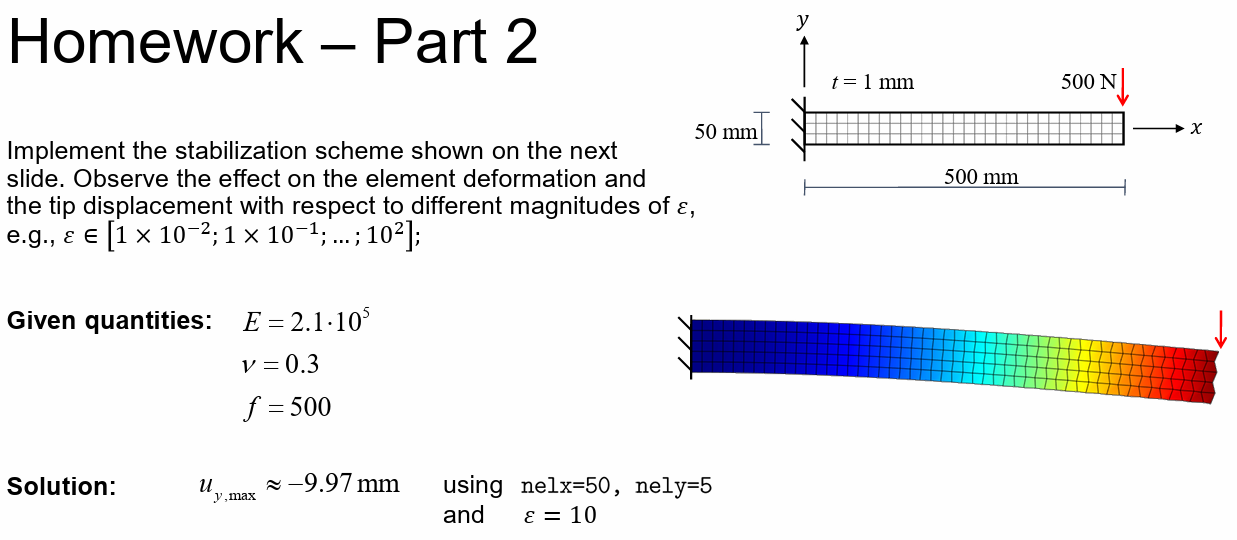

## Given parameters

E = 2.1e5;
nu = 0.3;

C = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0,  0, (1 - nu) / 2];

## Model definition

lx = 500;       % Length in x
ly = 50;        % Length in y
f0 = -500;      % Point load
t = 1;          % Thickness

#### Prepare geometry and mesh

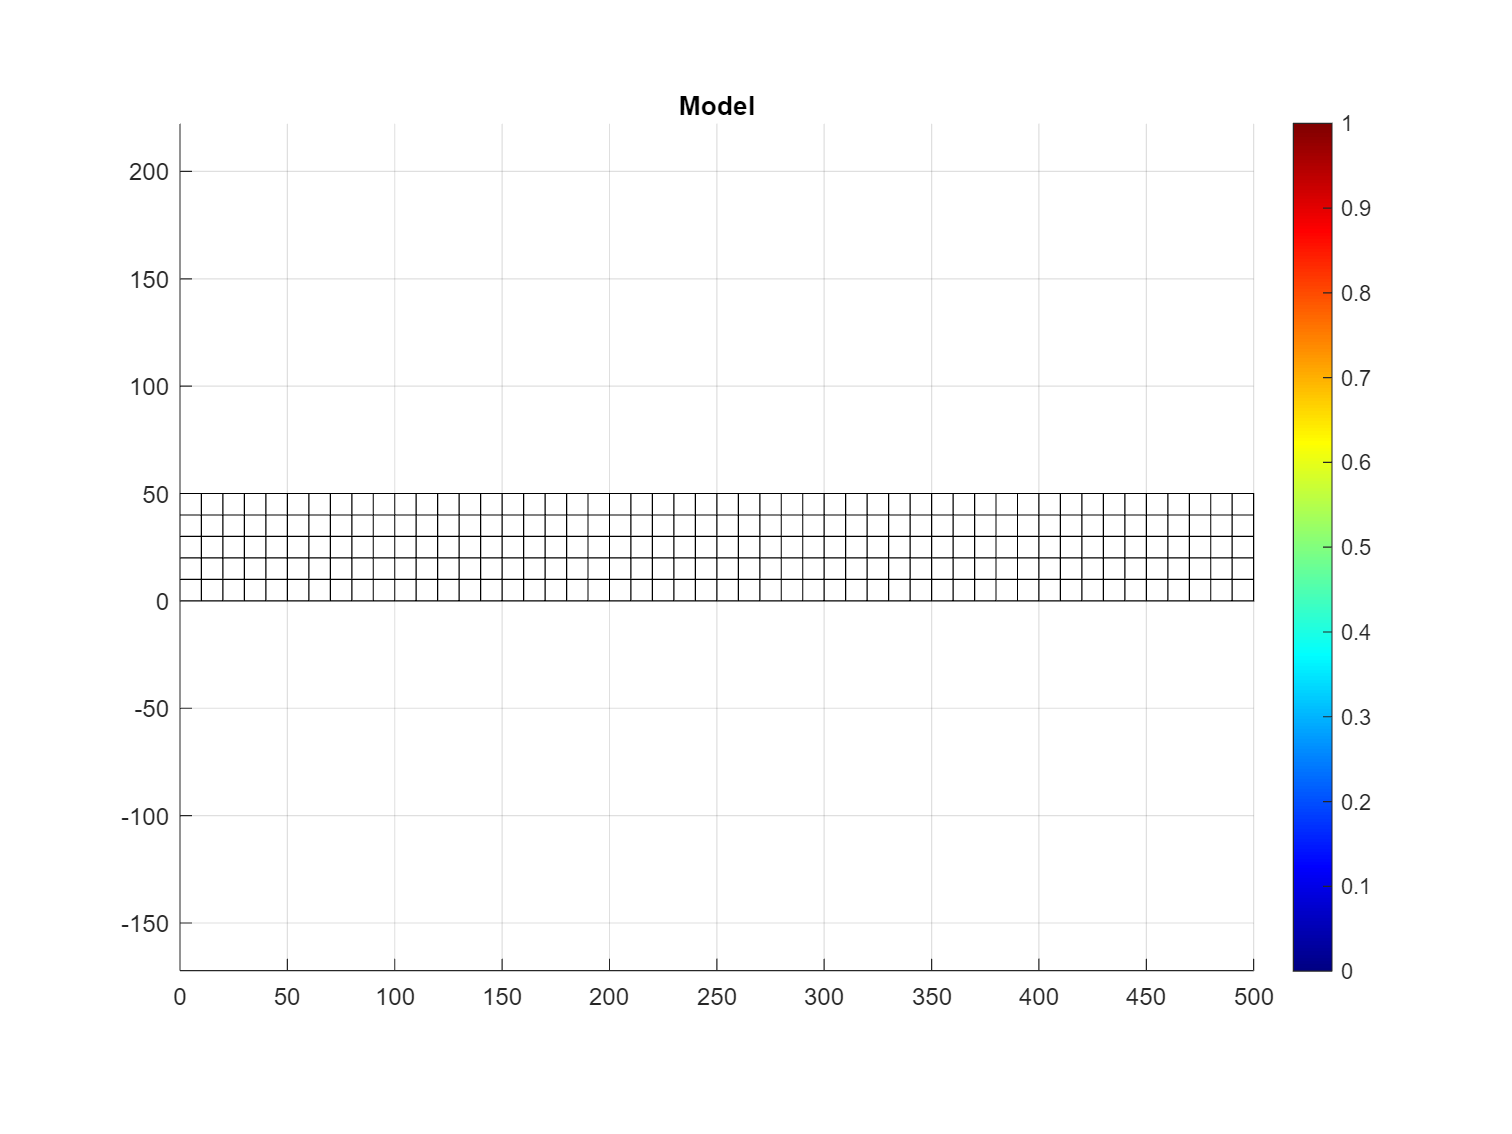

nelx = 50;      % Number of elements in x
nely = 5;       % Number of elements in y

elementType = 'quad';    % 'quad' or 'tri' for quadrilaterals or triangles, respectively
[nodes, elements] = rectangleMesh([lx, ly], [nelx, nely], elementType);

plotElements(nodes, elements, 'Model'); grid on;

nNodes = size(nodes, 1);
dofPerNode = 2;

nElements       = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement   = dofPerNode * nodesPerElement;
elementDOFs     = globalElementDOFs(elements, 2);

% Initialize system matrices
K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);

% Set up stiffness matrix by looping over elements
for e = 1 : nElements
    % Get element nodes
    elementNodes = nodes(elements(e, :), :);

    K_e_r_s = elementStiffnessLinearQuadSTABILIZATION(C, elementNodes);

    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elementDOFs(e, :), elementDOFs(e, :)) = K(elementDOFs(e, :), elementDOFs(e, :)) + K_e_r_s;
end

% Load
f([2 * (nelx + 1) * (nely + 1)]) = f0;

#### Boundary conditions

fixedNodes = find(nodes(:, 1) == 0);                % on the left edge, where x = 0 
fixeddofs = [2 * fixedNodes - 1; 2 * fixedNodes];

#### Solve system

freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);

#### Plot displacement as x0 + u

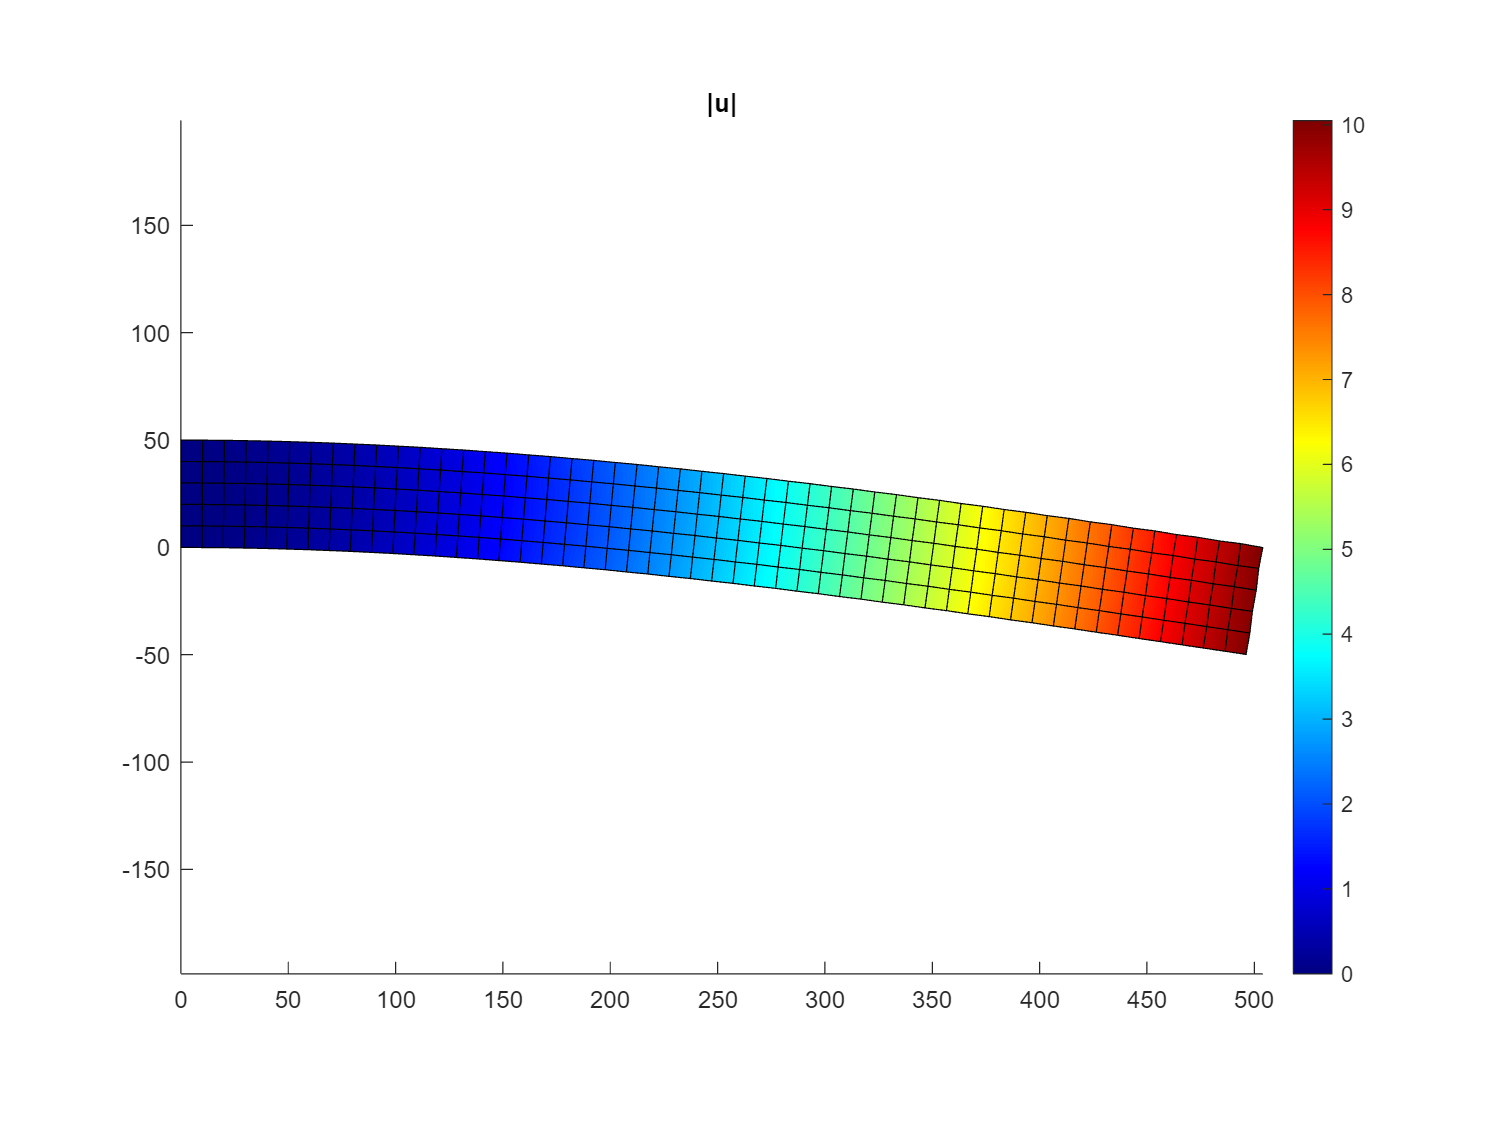

scale = 5;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
uMagnitude = vecnorm(uNodes, 2, 2);
plotElements(nodes + scale * uNodes, elements, '|u|', uMagnitude);

uTip = u(2 * (nelx + 1))

uTip = -9.9732

## Additional functions

#### Meshing

function [nodes, elements] = rectangleMesh(regionSize, nel, elementType)
    % Generates 2D structured quad mesh with dimensions and element count. Nodes sorted in rows of 
    % const x; optional transformation in 3D plane (e.g. for shells)
    % INPUT
    %   regionSize  (2 x 1 array)   Dimensions in x and y
    %   nel         (2 x 1 array)   Number of elements in x and y
    %   elementType (2 x 1 array)   'quad' or 'tri';
    % OUTPUT
    %   nodes      (n x 3 array)    Node coordinates
    %   elements   (n x 4 array)    Node indices per element

    nelx = nel(1);
    nely = nel(2);

    % Generate evenly spaced coordinates
    x = linspace(0,regionSize(1),nelx+1);
    y = linspace(0,regionSize(2),nely+1);

    % Use Matlab's ngrid to setup coordinates
    [X,Y] = ndgrid(x,y);
    nodes = [X(:), Y(:)];

    % Element numbering depending on elementType
    if strcmp(elementType, 'quad')
        elements = zeros(nelx * nely,4);
        for k = 1 : nely
            for m = 1: nelx
                elements((k - 1) * nelx + m, :) = [(k - 1) * (nelx + 1) + m, (k - 1) * (nelx + 1) + m + 1, ...
                                                    k * (nelx + 1) + m + 1, k * (nelx + 1) + m];
            end
        end
    elseif strcmp(elementType, 'tri')
        elements = zeros(2 * nelx * nely, 3);
        for n = 1 : nely
            % % SML lecture numbering
            firstTets = [1, 2, nelx + 2, ...
                        nelx + 3, nelx + 2, 2]' + (n - 1) * (nelx + 1);

            % Abaqus numbering
            % firstTets = [nelx + 2, 1, nelx + 3, ...
            %          2, nelx + 3, 1]' + (n - 1) * (nelx + 1);

            rowTets = reshape(firstTets + (0 : 1 : nelx - 1), 3, 2 * nelx);
            elementIndices = (n - 1) * 2 * nelx + 1 : n * 2 * nelx;
            elements(elementIndices, :) = rowTets';
        end
    else
        error('Element type not implemented.');
    end
end


#### Get GLOBAL Degrees of freedom

function elementDOFs = globalElementDOFs(elements, dim)
    % Return global DOFs for elements
    % INPUT
    %   elements (array)    nodes per element as (nElements x nodesPerElement) array
    %   dim (scalar)        dimension
    % OUTPUT
    %   elementDOFs (array) global DOFs per element as (nElements x (dim * nodesPerElement)) array

    switch dim
        case 1
            elementDOFs = elements;
        case 2
            nodes = reshape(elements', numel(elements), 1);
            elementDOFs = [2 * nodes - 1, 2 * nodes]';
            elementDOFs = transpose(reshape(elementDOFs(:), 2 * size(elements, 2), size(elements, 1)));
        otherwise
            error("not implemented");
    end
end

% Element stiffness
function KE = elementStiffnessLinearQuad(C, nodes)
    % Compute element stiffness matrix for linear quadrilateral element
    % INPUT
    %   C (array)                   Constitutive matrix
    %   nodes (array)               Nodes for element
    % OUTPUT
    %   KE (array)                  Element stiffness matrix

    % Prepare element stiffness matrix for mechanical analysis
    KE = zeros(size(nodes, 1) * size(nodes, 2));

    % Get gauss points
    integrationOrder = 2;
    [xg, wg] = gaussianPointsQuad(integrationOrder);
    
    % Integrate stiffness
    for g = 1 : size(xg, 1)
        % Compute jacobian for element at gauss point
        [~, dh] = linearQuadShapeFunctions(xg(g, 1), xg(g, 2));
        J = dh * nodes;
        detJ = det(J);

        % Get B matrix for stiffness integration
        dhdx = J \ dh;
        B = bMatrix(dhdx);

        % Evaluate summand for quadrature of element stiffness matrix
        KE = KE + wg(g) * B' * C * B * detJ;
    end

    %%TODO
    %%Add stabilization when using reduced integration

end

function K_e_r_s = elementStiffnessLinearQuadSTABILIZATION(C, nodes)
    % Compute element stiffness matrix for linear quadrilateral element
    % INPUT
    %   C (array)                   Constitutive matrix
    %   nodes (array)               Nodes for element
    % OUTPUT
    %   KE (array)                  Element stiffness matrix

    % Prepare element stiffness matrix for mechanical analysis
    KE = zeros(size(nodes, 1) * size(nodes, 2));

    % Get gauss points
    integrationOrder = 1;
    [xg, wg] = gaussianPointsQuad(integrationOrder);
    
    % Integrate stiffness
    for g = 1 : size(xg, 1)
        % Compute jacobian for element at gauss point
        [~, dh] = linearQuadShapeFunctions(xg(g, 1), xg(g, 2));
        J = dh * nodes;
        detJ = det(J);

        % Get B matrix for stiffness integration
        dhdx = J \ dh;
        B = bMatrix(dhdx);

        % Evaluate summand for quadrature of element stiffness matrix
        KE = KE + wg(g) * B' * C * B * detJ;
    end

    K_e_r = KE; 


    % STABILIZATION
    e_stabilization = 10;
    phi1 = [-1,0,1,0,-1,0,1,0]';
    phi2 = [0,-1,0,1,0,-1,0,1]';
    K_s   = e_stabilization*( phi1*phi1' + phi2*phi2' );

    K_e_r_s = K_e_r+K_s;

end

function KE = elementStiffnessLinearTri(C, nodes)
    % Compute element stiffness matrix for linear triangle element
    % INPUT
    %   C (array)                   Constitutive matrix
    %   nodes (array)               Nodes for element
    % OUTPUT
    %   KE (array)                  Element stiffness matrix
 
    
    %% TODO
    %% Prepare element stiffness matrix for mechanical analysis
    KE = zeros(size(nodes, 1) * size(nodes, 2));
    
    
    % Get gauss points
    integrationOrder = 1;
    [xg, wg] = gaussianPointsTri(integrationOrder);              % STEP1: GAUSS POINTS
    
    % Integrate stiffness
    [~, dh] = linearTriShapeFunctions(xg(1), ...                   % STEP2: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. r,s,t
                                      xg(2));              
    J = dh * nodes;                                             % STEP3: JACOBIAN

    dhdx = J \ dh; % inv(J) * dh;
    B = bMatrix(dhdx);                                          % STEP4: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. x,y,z -> B matrix

    KE = KE + wg * B' * C * B * abs(det(J));                    % STEP5: STIFFNESS MATRIX
end

% Shape functions
function [h, dh] = linearQuadShapeFunctions(r, s)
    % Evaluate shape functions for linear quadrilateral element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)           Shape functions at (r, s), row per given point
    %   dh (array)          Derivatives of shape functions at first (r, s)
    h1 = 1/4 * (1 - r) .* (1 - s);
    h2 = 1/4 * (1 + r) .* (1 - s);
    h3 = 1/4 * (1 + r) .* (1 + s);
    h4 = 1/4 * (1 - r) .* (1 + s);

    dh1dr = -1/4 * (1 - s);
    dh1ds = -1/4 * (1 - r);
    dh2dr = 1/4 * (1 - s);
    dh2ds = -1/4 * (1 + r);
    dh3dr = 1/4 * (1 + s);
    dh3ds = 1/4 * (1 + r);
    dh4dr = -1/4 * (1 + s);
    dh4ds = 1/4 * (1 - r);

    h = [h1, h2, h3, h4];
    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds;
          dh4dr, dh4ds]';
end

function [h, dh] = linearTriShapeFunctions(r, s)
    % Evaluate shape functions for linear triangular element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)           Shape functions at (r, s), row per given point
    %   dh (array)          Derivatives of shape functions at first (r, s)

    h1 = 1-r-s;
    h2 = r;
    h3 = s;

    dh1dr = -1;
    dh1ds = -1;

    dh2dr =  1;
    dh2ds =  0;
    
    dh3dr =  0;
    dh3ds =  1;

    h = [h1, h2, h3];

    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds]';
end

% B matrix
function B = bMatrix(dhdx)
    % Evaluate B matrix for linear quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   B (array)   B matrix for linear quadrilateral element in natural coordinates

    % Initialize B matrix
    B = zeros(3, 2 * size(dhdx, 2));

    % Define linear indices for first B matrix -> B1 corresponding to node 1
    indicesBi = [1; 5; 3; 6];
    indicesdHi = [1; 2; 2; 1];

    % Repeat indices for node 2 to node 4
    indicesB = indicesBi + (0 : 6 : 6 * size(dhdx, 2) - 6);
    indicesdH = indicesdHi + (0 : 2 : size(dhdx, 2) * 2 - 2);

    % Assign dh entries to B matrix
    B(indicesB) = dhdx(indicesdH);
end

% Integration points
function [xg, wg] = gaussianPointsQuad(n)
    % Return integration points and weights for 2D gauss integration of order n
    % INPUT
    %   n (scalar)      OPTIONAL, order for integration, default: 2
    % OUTPUT
    %   xg (array)      Gaussian points in 2D
    %   wg (array)      Combined weights for 2D integration points

    if nargin < 1
        n = 2;
    end
    
    switch n
        case 1
            xg = [0, 0];
            wg = 2 * 2;
        case 2
            xg = [-1/sqrt(3), -1/sqrt(3);
                   1/sqrt(3), -1/sqrt(3);
                   1/sqrt(3),   1/sqrt(3);
                  -1/sqrt(3),  1/sqrt(3);];
            wg = ones(4,1);
        case 3
            xg = [-sqrt(3/5), -sqrt(3/5);
                  0, -sqrt(3/5);
                  sqrt(3/5), -sqrt(3/5);
                  -sqrt(3/5), 0;
                  0, 0;
                  sqrt(3/5), 0;
                  -sqrt(3/5), sqrt(3/5);
                  0, sqrt(3/5);
                  sqrt(3/5), sqrt(3/5)];
            wg = [5/9 * 5/9;
                  8/9 * 5/9;
                  5/9 * 5/9;
                  5/9 * 8/9;
                  8/9 * 8/9;
                  5/9 * 8/9;
                  5/9 * 5/9;
                  8/9 * 5/9;
                  5/9 * 5/9];
        otherwise
            error('Integration points for order %d not implemented', n);
    end
end

function [xg, wg] = gaussianPointsTri(n)
    % Return integration points and weights for 2D gauss integration of triangular element
    % INPUT
    %   n (scalar)      OPTIONAL, "order" for integration, default: 1
    % OUTPUT
    %   xg (array)      Gaussian points in 2D
    %   wg (array)      Combined weights for 2D integration points

    % Default: 1 integration point
    if nargin < 1
        n = 1;
    end

    switch n
        case 1
            xg = [1/3, 1/3];
            wg = [1/2];
        case 2
            xg = [1/2, 0;
                  0, 1/2;
                  1/2, 1/2];
            wg = 1/6 * ones(3,1);
        case 3
            xg = [1/6, 1/6;
                2/3, 1/6;
                1/6, 2/3];
            wg = 1/6 * ones(3,1);
        otherwise
            error('Integration points for order %d of triangle not implemented', n);
    end            
end


% Plot functions
function p = plotElements(nodes, elements, title, color)
    % Plot elements by plotting a patch for each element
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array
    %   color (array)       OPTIONAL: Color for nodes or elements per row
    % OUTPUT
    %   p (array)           Patches for elements

    newFigure(title);
    hold on;
    for e = 1 : size(elements, 1)
        elementNodes = nodes(elements(e, :), :);
        p(e) = patch(elementNodes(:, 1), elementNodes(:, 2), 'w');
        if nargin > 3
            if size(color, 1) == size(nodes, 1)
                % Interpolate between nodal values
                p(e).set('FaceColor', 'interp', 'FaceVertexCData', color(elements(e, :)));
            elseif size(color, 1) == size(elements, 1)
                % Color per element
                p(e).set('FaceColor', 'flat', 'FaceVertexCData', color(e));
            end
            clim([min(color), max(color)]);
            % p(e).EdgeAlpha = 0;
        else
            p(e).FaceAlpha = 0;
        end
    end
    hold off;
end

function f = newFigure(figureTitle)
    % Open figure and set several common options
    % INPUT
    %   figureTitle (string/char array)     OPTIONAL: title for figure
    % OUTPUT
    %   f (figure) 

    f = figure;
    f.Position([3, 4]) = 1.5 * f.Position([3, 4]);
    f.Position(2) = f.Position(2) - f.Position(4)/3;
    axis equal; 
    colormap jet;
    colorbar;
    if nargin > 0
        title(figureTitle);
    end
end